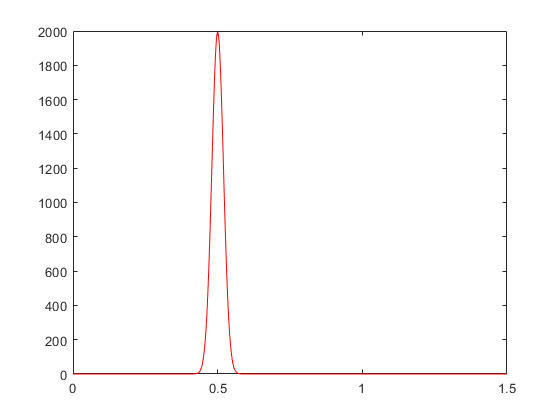

clc;clear all;
%生成高斯函数
spectrum_frequency = 0:0.001:2;
spectrum_intensity = 100*Gaussian(spectrum_frequency,0.5,0.02);
plot(spectrum_frequency,spectrum_intensity,'r');
xlim([0 1.5])

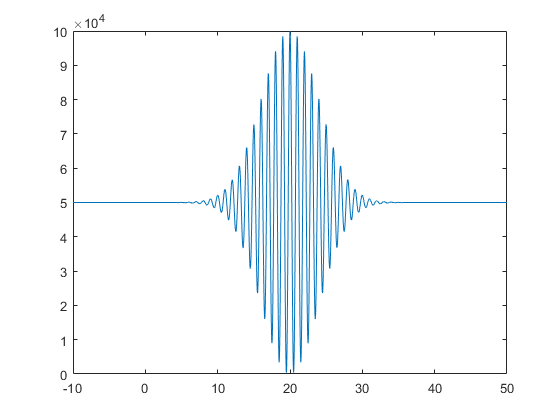

%生成白光干涉信号
z0 = 20;    %单位为微米
N = 40000;
z = -10:50/40000:(N-1)*(50/40000);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency));
end
%disp("生成的白光干涉信号");
plot(z,interference_signal);

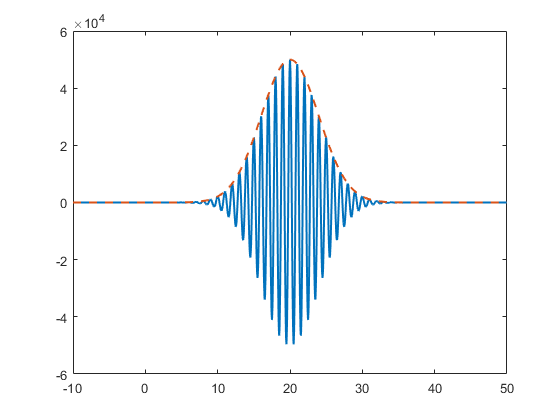

interference_signal = interference_signal-mean(interference_signal);
baoluo = hilbert(interference_signal); % Hilbert变换
baoluo = abs(baoluo);
plot(z,interference_signal,z,baoluo,'--','linewidth',1.5);

改变高斯光谱的中心波长和半高宽（FWHM）.

当中心波长为500时，半高宽分别为50~200，高斯光谱的FWHM为$2\sqrt{2\mathrm{ln2}}*\sigma$,通过设置$\sigma$来改变半高宽。

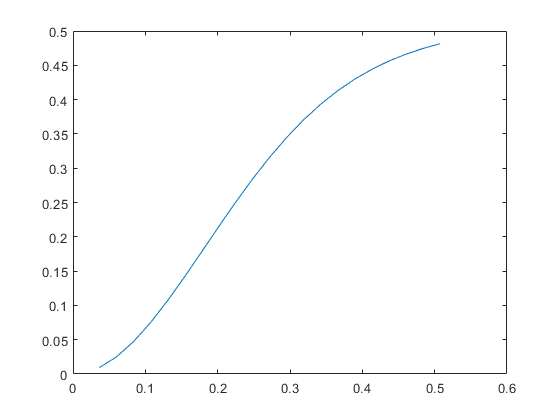

cenlam = 0.5;
sigma = 0.0155:0.01:0.22;
V = zeros(1,length(sigma));
W = zeros(1,length(sigma));
for n = 1:length(sigma)
spectrum_intensity = 100*Gaussian(spectrum_frequency,cenlam,sigma(n));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency));
end
%计算零级条纹与第一级条纹的可见度和干涉条纹的空间长度
V(n) = calcuV(interference_signal);
W(n) = calcuW(z,interference_signal);
end
FWHM = 2*sqrt(2*(log(2)))*sigma;
plot(FWHM,V);

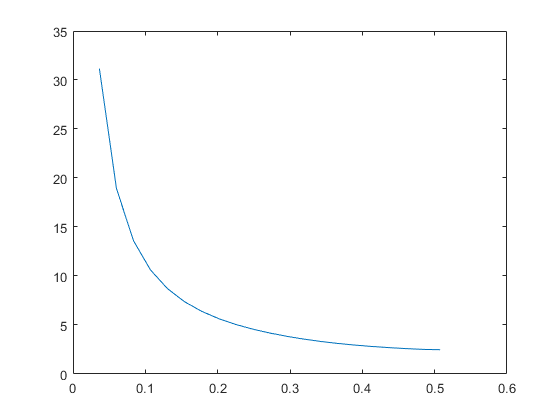

plot(FWHM,W);

从空域来看，如果白光干涉信号光谱是高斯型状的，且在没有色散和噪声的情况下，高斯光谱生成的白光干涉信号在空间域中的包络为高斯型的。包络最大值可以认为和白光干涉信号最大值一致。固定中心波长不变，改变半高宽的情况下，随着半高宽逐渐增大，零级条纹与第一级条纹的可见度逐渐增加。但干涉条纹的空间长度随着半高宽的增大逐渐减小。对于空域求解相干峰顶点的算法，`零级条纹相比于其它级次条纹的强度差值直接关系到相干峰感知算法`。`零级条纹与一级条纹的可见度越大，相干峰感知算法越精确。`干涉条纹的空间长度越小，白光干涉信号用作物体表面形貌测量时，测量的精度越高，效果越好。可见固定中心波长不变，增加高斯光谱的FWHM有利于白光干涉在空域的测量。

%对白光干涉信号作傅里叶变换，选择正频域部分，然后再作傅里叶逆变换，可以白光干涉信号的幅度谱和相位谱。
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
spectrum_frequency = 0:0.001:2;
cenlam = 0.5;
% sigma111 = 0.0155:0.02:0.22;
% for n = 1:length(sigma)
spectrum_intensity = 100*Gaussian(spectrum_frequency,cenlam,0.02);
plot(spectrum_frequency,spectrum_intensity,'r');
xlim([0 1.5])

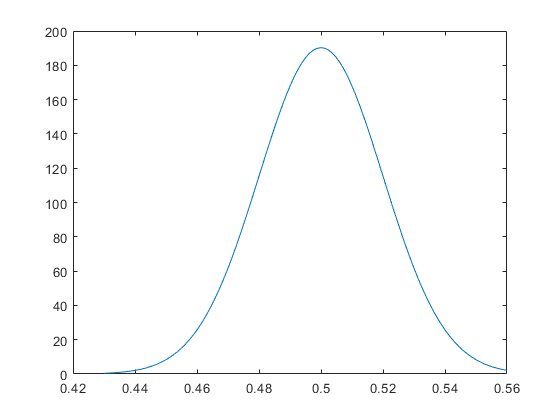

%生成白光干涉信号
z0 = 20;    %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency));
end
interference_signal = interference_signal-mean(interference_signal);
%fft补零
Nftt = 2^18;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
abs_fis = abs(f_interference_signal(1:Nftt/2+1))*2/Nftt;
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-0.43));
[~, indix_max] = min(abs(sigma-0.56));
% ang_fis = unwrap(ang_fis(indix_min:indix_max));
plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max));

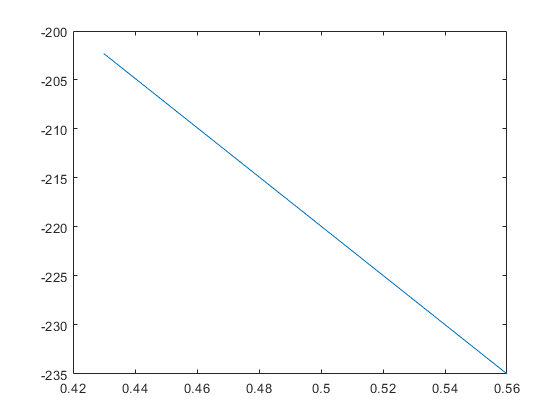

plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max));

p1 = polyfit(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),1)

p1 =  -251.3274  -94.2478


p1(1) = p1(1)-4*pi*z(1);
%计算z0,误差
a01 = wrapToPi(p1(2))

a01 = 1.1543e-06

p1(1) = p1(1)-4*pi*z(1)

p1 =  -251.3274  -94.2478


calculate_z0 = p1(1)/(-4*pi)

calculate_z0 = 20.0000

diff_z0 = abs(calculate_z0-z0)

diff_z0 = 1.7313e-07

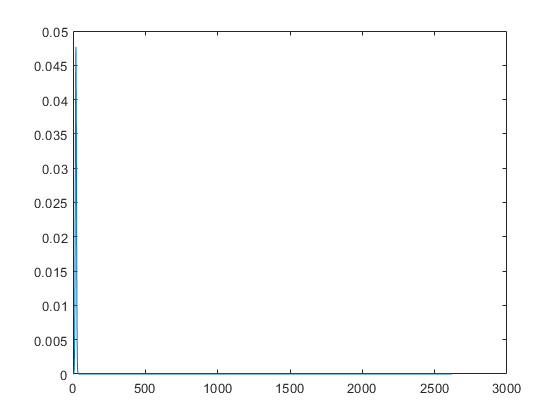

pSigma = -4*pi*calculate_z0*sigma;
F_sigma = abs_fis.*exp(1i*pSigma);

%逆傅里叶变换
Nifft = 2^20;
interference_signal1 = ifft(F_sigma,Nifft);
deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
deltaZ = 1/(2*Nifft*deltaSigma);
zData = (1:Nifft)*deltaZ;
intensity = abs(interference_signal1);
phase = angle(interference_signal1);
plot(zData,intensity);

% plot(zData,phase);
[~,index3]= max(intensity);
% plot(zData,intensity);xlim([zData(index3)-2 zData(index3)+2]);
% plot(zData,phase);xlim([zData(index3)-2 zData(index3)+2]);
za1 = zData(index3);
%-----------------------------------
[~,indexend] = min(abs(zData-(za1+0.5)));
[~,indexstart] = min(abs(zData-(za1-0.5)));
unwrapZend = zData(indexend);
unwrapZ_1 = zData(indexstart);
unwrapN1 = index3;
unwrapNe = find(zData==unwrapZend);
unwrapN_1 = find(zData==unwrapZ_1);
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index3);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N

zp1 = 20.0025

za1

za1 = 20.0025

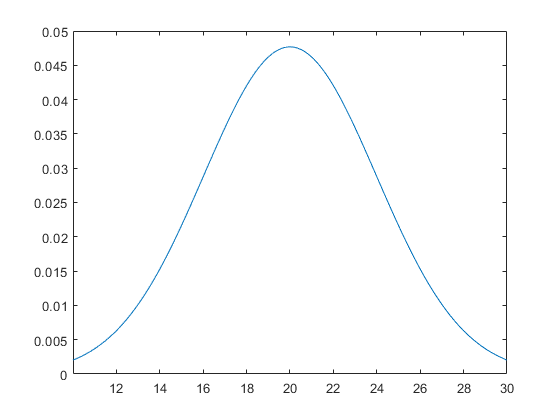


% end
plot(zData,intensity);xlim([zData(index3)-10 zData(index3)+10]);

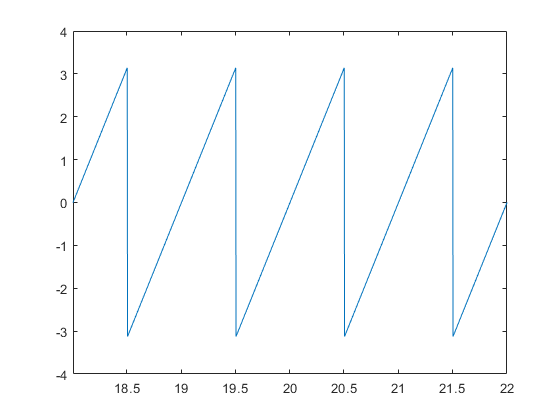

plot(zData,phase);xlim([zData(index3)-2 zData(index3)+2]);

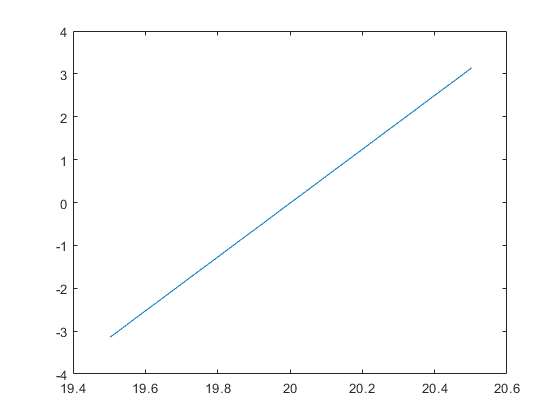

plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));

从白光干涉信号幅度谱和相位谱可以看出，由高斯光谱生成的白光干涉信号的幅度谱是成高斯分布的，且幅度谱最大值和相位谱零点相等，均等于物体表面形貌的位置。固定中心波长不变，改变半高宽的情况下，随着半高宽逐渐增大，幅度谱的半高宽逐渐减小，相位谱不变。这说明增大高斯光谱半高宽有利于计算幅度谱最大值，从而有利于白光干涉测量。

function [y] = Gaussian(x,mu,sigma)
y = 1/(sqrt(2*pi)*sigma)*exp(-(x-mu).^2/(2*sigma^2));
end

条纹可见度公式：V= （I0-I1）/I0

%零级条纹与第一级条纹的可见度
function V = calcuV(signal)
[pks,~] = findpeaks(signal);
pks = sort(pks,'descend');
V = (pks(1)-pks(2))/pks(1);
end

%计算干涉条纹的空间长度
function wdt = calcuW(z,signal)
signal = signal-mean(signal);
%得到信号包络
W = hilbert(signal); % Hilbert变换
W = abs(W);
% plot(z,signal,z,W,'--','linewidth',1.5)
idx = find(diff(sign(W-max(W)/100)));
    for n = 1:numel(idx)
        idxrng = idx(n)-2:idx(n)+2;
        xfwhm(1,n) = interp1(W(idxrng), z(idxrng), max(W)/100, 'pchip');
    end
    wdt = xfwhm(end)-xfwhm(1);
end